Preparation

% Afficher une IMR
% imagesc(T1_S{20});
% axis image;
% colormap(gray);
% colorbar;

% Role of randperm
% randperm(6)
% randperm(6,3)


% Vectorization of an image matrix
% img = T1_S{20}
% img(:)

% Choix aleatoire
% cell_try = cell(1,10);
% for i = 1:10
%     cell_try{i} = T2_S{i*3}; 
% end
% indices = randperm(10)
% 
% 
% X_Train = zeros(4096,8);
% 
% cell_try
% 
% for i = 1:8
%     X_Train(:,i) = cell_try{indices(i)}(:);
% end

% images = cell(1,3);
% images{1} = PD_A;
% sum(sum(images{1}{1} - PD_A{1}))

% Best one is below this block


% clear all;
% close all;
% clc;
% addpath('../');
% 
% %-- Load database parameters
% filename = './data/data_Clanu_22.mat';
% load(filename);
% 
% nC = 9;
% %-- put database in place
% [database,indices] = database.structure_database(T1_A,T1_C,T1_S,T2_A,T2_C,T2_S,PD_A,PD_C,PD_S,nC);
% 
% % % -- Display training database
% visu.display_clanu_database(database);
% 
% 
% %-- Build a model with a n_h-dimensional hidden layer
% num_iterations =2000;
% learning_rate = 0.01 ;
% print_cost = true;
% nX = size(database.X_train,1);
% 
% layers_dims = [nX,9,9,9,nC];
% [parameters,costs] = L_layers_nn.model(database, layers_dims, num_iterations, learning_rate, print_cost);
% 
% 
% %-- Compute accuracy
% X_train = database.X_train;
% Y_train = database.Y_train;
% X_test = database.X_test;
% Y_test = database.Y_test;
% 
% 
% nB =  size(database.Y_train,2);
% Y_train_c = sum(([1:nC]'*ones(1,nB)).*Y_train , 1); 
% nB =  size(database.Y_test,2);
% Y_test_c = sum(([1:nC]'*ones(1,nB)).*Y_test , 1); 
% 
% Y_prediction_train = L_layers_nn.predict(parameters, X_train);
% Y_prediction_test = L_layers_nn.predict(parameters, X_test);
% 
% 
% %-- Print train/test Errors
% disp(['train accuracy: ', num2str(100 - mean(sum(abs(Y_prediction_train - Y_train_c),1)) * 100), ' %'])
% disp(['test accuracy: ', num2str(100 - mean(sum(abs(Y_prediction_test - Y_test_c),1)) *100)  , ' %']) 

### Best

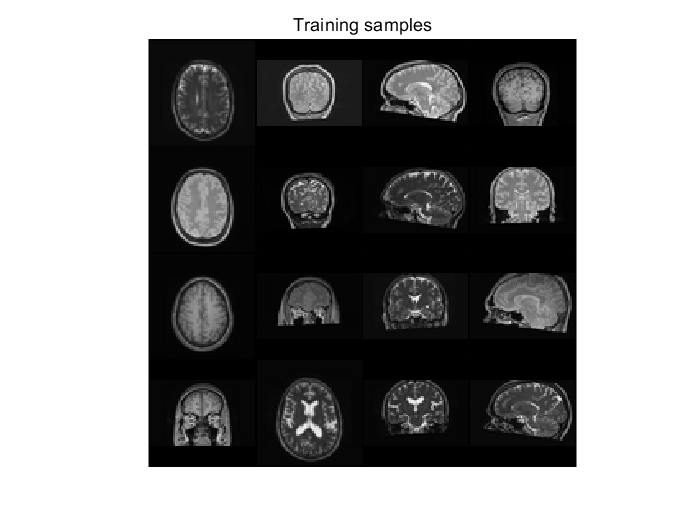

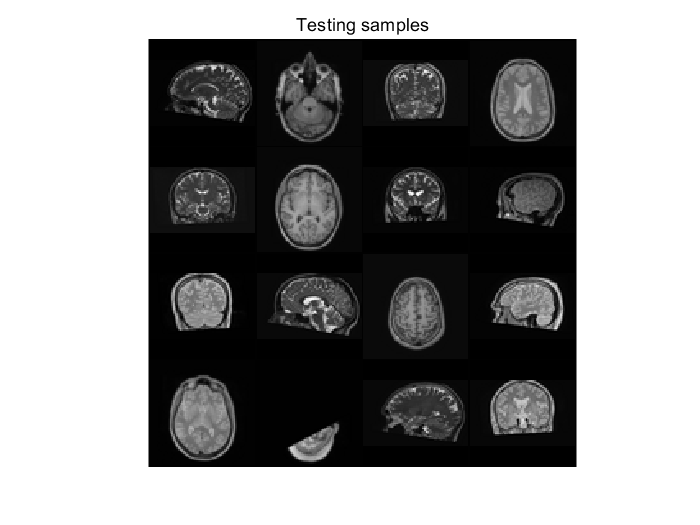

clear all;
close all;
clc;
addpath('../');

%-- Load database parameters
filename = './data/data_Clanu_22.mat';
load(filename);

nC = 9;
%-- put database in place
[database,indices] = database.structure_database(T1_A,T1_C,T1_S,T2_A,T2_C,T2_S,PD_A,PD_C,PD_S,nC);

% % -- Display training database
visu.display_clanu_database(database);

Cost after iteration 100: 2.3517
Cost after iteration 200: 1.8454
Cost after iteration 300: 1.5233
Cost after iteration 400: 1.282
Cost after iteration 500: 1.0995
Cost after iteration 600: 0.95607
Cost after iteration 700: 0.8408
Cost after iteration 800: 0.74667
Cost after iteration 900: 0.66869
Cost after iteration 1000: 0.60328
Cost after iteration 1100: 0.5478
Cost after iteration 1200: 0.50027
Cost after iteration 1300: 0.45922
Cost after iteration 1400: 0.42348
Cost after iteration 1500: 0.39216
Cost after iteration 1600: 0.36455
Cost after iteration 1700: 0.34007
Cost after iteration 1800: 0.31826
Cost after iteration 1900: 0.29875
Cost after iteration 2000: 0.28122


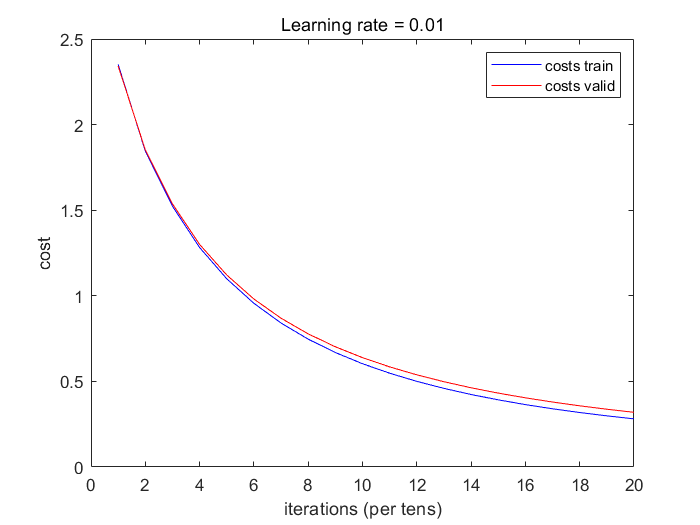



%-- Build a model with a n_h-dimensional hidden layer
num_iterations =2000;
learning_rate = 0.01 ;
print_cost = true;
nX = size(database.X_train,1);

layers_dims = [nX,64,32,16,nC];
[parameters,costs] = L_layers_nn.model(database, layers_dims, num_iterations, learning_rate, print_cost);



%-- Compute accuracy
X_train = database.X_train;
Y_train = database.Y_train;
X_test = database.X_test;
Y_test = database.Y_test;


nB =  size(database.Y_train,2);
Y_train_c = sum(([1:nC]'*ones(1,nB)).*Y_train , 1); 
nB =  size(database.Y_test,2);
Y_test_c = sum(([1:nC]'*ones(1,nB)).*Y_test , 1); 

Y_prediction_train = L_layers_nn.predict(parameters, X_train);

nc = 9

Y_prediction_test = L_layers_nn.predict(parameters, X_test);

nc = 9



%-- Print train/test Errors
disp(['train accuracy: ', num2str(100 - mean(sum(abs(Y_prediction_train - Y_train_c),1)) * 100), ' %'])

train accuracy: 100 %


disp(['test accuracy: ', num2str(100 - mean(sum(abs(Y_prediction_test - Y_test_c),1)) *100)  , ' %'])    

test accuracy: 86.6667 %
